# 1. Um aluno do primeiro ano de um curso de Engenharia tem todas as semanas 2 aulas Teorico-Praticas de uma Unidade Curricular X as 9:00, as quartas e sextas. Todos os dias que tem aulas desta UC, o aluno decide se vai a aula ou nao da seguinte forma: Se tiver estado presente na aula anterior a probabilidade de ir a aula e 70%; se faltou a anterior, a probabilidade de ir e 80%.

## a) Se estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte?

   % NF  F
% NF 0.7 0.8
% F  0.3 0.2
M = [0.7 0.8
    0.3 0.2];
x = [1 0]';
p = M^2*x;
disp(p(1,1));

    0.7300



## b) Se nao estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte?

x = [0 1]';
p = M^2*x;
disp(p(1,1));

    0.7200



## c) Sabendo que esteve presente na primeira aula, qual a probabilidade de estar na ultima aula, assumindo que o semestre tem exactamente 15 semanas de aulas e nao existem feriados?

x = [1 0]';
% 29 aulas que faltam
p = M^29*x;
disp(p(1,1));

    0.7273



## d) Represente num grafico a probabilidade de faltar a cada uma das 30 aulas, assumindo que a probabilidade de estar presente na primeira aula e de 85%.

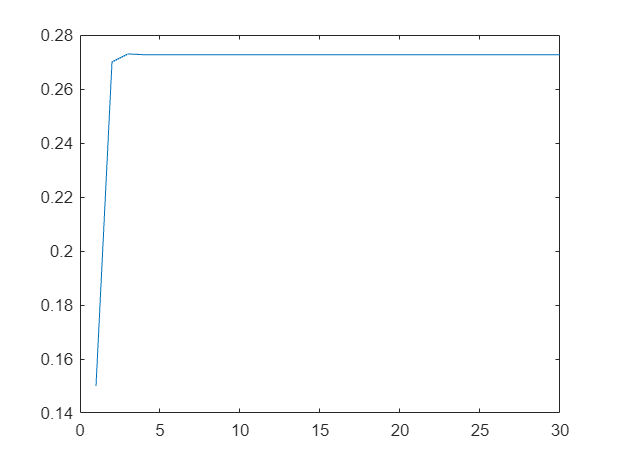

probs = ones(1,30);
probs(1) = 0.15;
for i=2:30
    p = M^i*x;
    probs(i) = p(2,1);
end
plot(probs);